syms x
f = @(x) x^3

f = function_handle with value:
    @(x)x^3


diff(f(x),x,3)

$$ans = 6$$

syms y(t)
edo1 = diff(y(t),t)==y(t)

$$edo1 = \frac{\partial }{\partial t}y\left(t\right)=y\left(t\right)$$

significa dy/dt=y

clear all

O comando quiver(a,b,u,v) representa o vetor (u,v) partindo do ponto (a,b)

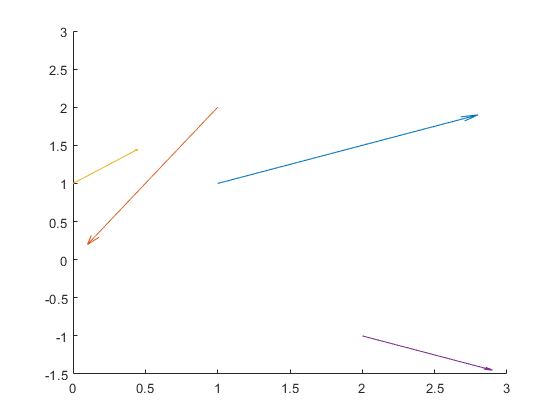

hold on
quiver(1,1,2,1)
quiver(1,2,-1,-2)
quiver(0,1,0.5,0.5)
quiver(2,-1,1,-0.5)
hold off
grid off
xlim([0.00 3.00])
ylim([-1.50 3.00])

clear all
f = @(t,y) t .* y .^ 2

f = function_handle with value:
    @(t,y)t.*y.^2


[t,y]=meshgrid(-2:0.2:2,-2:0.2:2);
u = ones(length(t));
v = f(t,y);
l=sqrt(1+v.^2)

l =    8.062257748298549   7.269112738154499   6.477653896280660   5.688585061331157   4.903060268852505   4.123105625617661   3.352610922848041   2.600000000000000   1.886796226411320   1.280624847486570   1.000000000000000   1.280624847486570   1.886796226411320   2.600000000000000   3.352610922848041   4.123105625617661   4.903060268852505   5.688585061331157   6.477653896280660   7.269112738154499   8.062257748298549
   6.556706490304412   5.917112809470511   5.279569679434112   4.644921527862445   4.014541567850555   3.390811112403639   2.778212374891452   2.186123509777067   1.636953267506437   1.191597247395277   1.000000000000000   1.191597247395277   1.636953267506437   2.186123509777067   2.778212374891452   3.390811112403639   4.014541567850555   4.644921527862445   5.279569679434112   5.917112809470511   6.556706490304412
   5.216742278472267   4.715258635536339   4.216303594382170   3.720894516107653   3.230663089831560   2.748381341808302   2.279101577376489   1.832838236

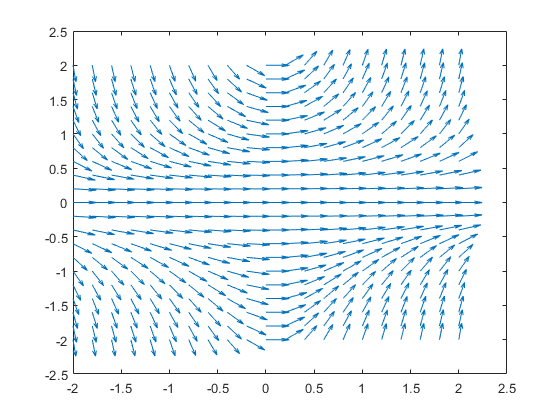

quiver(t,y,u./l,v./l)

clear all
syms t y
f = @(t,y) 2 - t .* y

f = function_handle with value:
    @(t,y)2-t.*y


[t,y] = meshgrid(-2:0.5:2,-2:0.5:2)

t =   -2.000000000000000  -1.500000000000000  -1.000000000000000  -0.500000000000000                   0   0.500000000000000   1.000000000000000   1.500000000000000   2.000000000000000
  -2.000000000000000  -1.500000000000000  -1.000000000000000  -0.500000000000000                   0   0.500000000000000   1.000000000000000   1.500000000000000   2.000000000000000
  -2.000000000000000  -1.500000000000000  -1.000000000000000  -0.500000000000000                   0   0.500000000000000   1.000000000000000   1.500000000000000   2.000000000000000
  -2.000000000000000  -1.500000000000000  -1.000000000000000  -0.500000000000000                   0   0.500000000000000   1.000000000000000   1.500000000000000   2.000000000000000
  -2.000000000000000  -1.500000000000000  -1.000000000000000  -0.500000000000000                   0   0.500000000000000   1.000000000000000   1.500000000000000   2.000000000000000
  -2.000000000000000  -1.500000000000000  -1.000000000000000  -0.500000000000000           

y =   -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000
  -1.500000000000000  -1.500000000000000  -1.500000000000000  -1.500000000000000  -1.500000000000000  -1.500000000000000  -1.500000000000000  -1.500000000000000  -1.500000000000000
  -1.000000000000000  -1.000000000000000  -1.000000000000000  -1.000000000000000  -1.000000000000000  -1.000000000000000  -1.000000000000000  -1.000000000000000  -1.000000000000000
  -0.500000000000000  -0.500000000000000  -0.500000000000000  -0.500000000000000  -0.500000000000000  -0.500000000000000  -0.500000000000000  -0.500000000000000  -0.500000000000000
                   0                   0                   0                   0                   0                   0                   0                   0                   0
   0.500000000000000   0.500000000000000   0.500000000000000   0.500000000000000   0.500000

u = ones(length(t))

u =      1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1


v = f(t,y)

v =   -2.000000000000000  -1.000000000000000                   0   1.000000000000000   2.000000000000000   3.000000000000000   4.000000000000000   5.000000000000000   6.000000000000000
  -1.000000000000000  -0.250000000000000   0.500000000000000   1.250000000000000   2.000000000000000   2.750000000000000   3.500000000000000   4.250000000000000   5.000000000000000
                   0   0.500000000000000   1.000000000000000   1.500000000000000   2.000000000000000   2.500000000000000   3.000000000000000   3.500000000000000   4.000000000000000
   1.000000000000000   1.250000000000000   1.500000000000000   1.750000000000000   2.000000000000000   2.250000000000000   2.500000000000000   2.750000000000000   3.000000000000000
   2.000000000000000   2.000000000000000   2.000000000000000   2.000000000000000   2.000000000000000   2.000000000000000   2.000000000000000   2.000000000000000   2.000000000000000
   3.000000000000000   2.750000000000000   2.500000000000000   2.250000000000000   2.000000

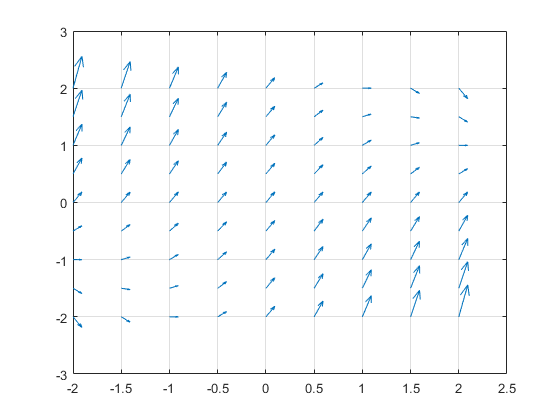

quiver(t,y,u,v)
grid on;

clear all
f = @(t,y) 2 - t.*y

f = function_handle with value:
    @(t,y)2-t.*y


intervalo = [-2,2]

intervalo =     -2     2


[t,y] = ode45(f,intervalo,-1)

t =   -2.000000000000000
  -1.900000000000000
  -1.800000000000000
  -1.700000000000000
  -1.600000000000000
  -1.500000000000000
  -1.400000000000000
  -1.300000000000000
  -1.200000000000000
  -1.100000000000000


y =   -1.000000000000000
  -0.994669095804680
  -0.977282747292452
  -0.945792160267827
  -0.898204086793861
  -0.832647974693451
  -0.747514599370689
  -0.641601042589036
  -0.514179957624896
  -0.365065612716626


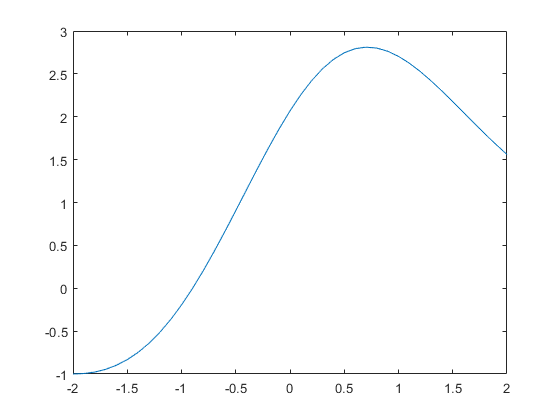

plot(t,y)

clear all
syms t y
f = @(t,y) 2 - t.*y

f = function_handle with value:
    @(t,y)2-t.*y


[t,y] = meshgrid(-5:0.3:5,-5:0.3:5)

t =   -5.000000000000000  -4.700000000000000  -4.400000000000000  -4.100000000000000  -3.800000000000000  -3.500000000000000  -3.200000000000000  -2.900000000000000  -2.600000000000000  -2.300000000000000  -2.000000000000000  -1.700000000000000  -1.400000000000000  -1.100000000000000  -0.800000000000000  -0.500000000000000  -0.200000000000000   0.100000000000001   0.400000000000000   0.700000000000000   1.000000000000000   1.300000000000001   1.600000000000001   1.900000000000000   2.200000000000001   2.500000000000000   2.800000000000000   3.100000000000001   3.400000000000000   3.700000000000000   4.000000000000000   4.300000000000001   4.600000000000001   4.900000000000000
  -5.000000000000000  -4.700000000000000  -4.400000000000000  -4.100000000000000  -3.800000000000000  -3.500000000000000  -3.200000000000000  -2.900000000000000  -2.600000000000000  -2.300000000000000  -2.000000000000000  -1.700000000000000  -1.400000000000000  -1.100000000000000  -0.800000000000000  -0.5000000000

y =   -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000  -5.000000000000000
  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.700000000000000  -4.7000000000

u = ones(length(t))

u =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1  

v = f(t,y)

v =  -23.000000000000000 -21.500000000000000 -20.000000000000000 -18.500000000000000 -17.000000000000000 -15.500000000000000 -14.000000000000000 -12.500000000000000 -11.000000000000000  -9.500000000000002  -8.000000000000000  -6.500000000000000  -5.000000000000002  -3.500000000000000  -1.999999999999999  -0.500000000000000   0.999999999999999   2.500000000000003   4.000000000000002   5.500000000000001   7.000000000000002   8.500000000000004  10.000000000000004  11.500000000000002  13.000000000000004  14.500000000000002  16.000000000000000  17.500000000000004  19.000000000000000  20.500000000000000  22.000000000000000  23.500000000000004  25.000000000000004  26.500000000000000
 -21.500000000000000 -20.090000000000003 -18.680000000000003 -17.270000000000000 -15.859999999999999 -14.449999999999999 -13.040000000000001 -11.630000000000001 -10.220000000000001  -8.810000000000002  -7.400000000000000  -5.990000000000001  -4.580000000000002  -3.170000000000001  -1.759999999999999  -0.3500000000

l=sqrt(1+v.^2)

l =   23.021728866442675  21.523243250030884  20.024984394500787  18.527007313648905  17.029386365926403  15.532224567009067  14.035668847618199  12.539936203984453  11.045361017187261   9.552486587271401   8.062257748298549   6.576473218982953   5.099019513592786   3.640054944640259   2.236067977499789   1.118033988749895   1.414213562373094   2.692582403567255   4.123105625617662   5.590169943749475   7.071067811865477   8.558621384311849  10.049875621120893  11.543396380615198  13.038404810405300  14.534441853748636  16.031219541881399  17.528548142958108  19.026297590440446  20.524375751773793  22.022715545545239  23.521266972678152  25.019992006393611  26.518861212352238
  21.523243250030884  20.114872607103436  18.706747445774749  17.298927712433507  15.891494580435158  14.484560745842449  13.078287349649418  11.672913089713298  10.268807136177015   8.866572054633068   7.467261881037788   6.072898813581535   4.687899316324959   3.323988567970715   2.024252948620799   1.0594810050

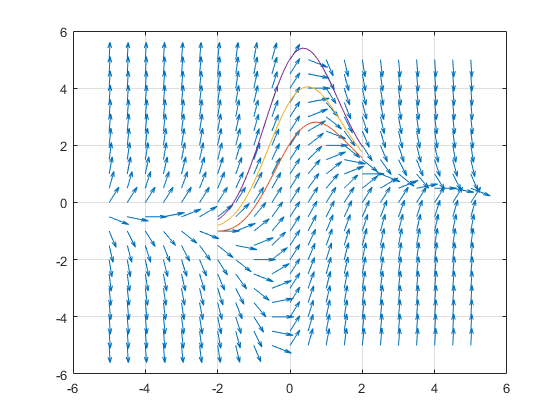

grid on

quiver(t,y,u./l,v./l)
t0 = [-2,2]

t0 =     -2     2


y0 = [-1:0.2:-0.5]

y0 =   -1.000000000000000  -0.800000000000000  -0.600000000000000


[t,y]= ode45(f,t0,y0)

t =   -2.000000000000000
  -1.962321703527356
  -1.924643407054713
  -1.886965110582069
  -1.849286814109425
  -1.749286814109425
  -1.649286814109425
  -1.549286814109425
  -1.449286814109425
  -1.349286814109425


y =   -1.000000000000000  -0.800000000000000  -0.600000000000000
  -0.999272210988277  -0.783771475444975  -0.568270739901673
  -0.997016661338069  -0.765143212774547  -0.533269764211024
  -0.993124156260581  -0.743988114194731  -0.494852072128880
  -0.987484273145371  -0.720180270553168  -0.452876267960965
  -0.963215558398591  -0.643217577582760  -0.323219596766929
  -0.923795583400636  -0.544523014478574  -0.165250445556512
  -0.867299112057873  -0.422249491109741   0.022800129838392
  -0.792004930146459  -0.274972147643867   0.242060634858726
  -0.696470908056163  -0.101781116421339   0.492908675213486


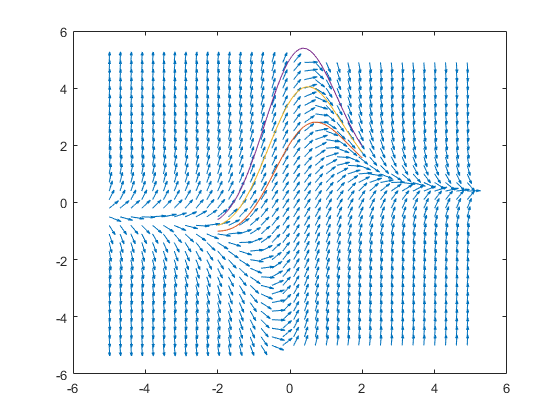

hold on
plot(t,y)
hold off

Colocar o que está entre o hold on e o hold off para plotar junto a curva da solução do valor inicial da edo.

Para expressar um único valor de y0 não precisa definir o y0, apenas trocar y0 pelo valor inicial desejado, veja a seguir

clear all
syms t y
f = @(t,y) 2 - t.*y

f = function_handle with value:
    @(t,y)2-t.*y


[t,y] = meshgrid(-2:0.3:2,-2:0.3:2)

t =   -2.000000000000000  -1.700000000000000  -1.400000000000000  -1.100000000000000  -0.800000000000000  -0.500000000000000  -0.200000000000000   0.100000000000000   0.400000000000000   0.700000000000000   1.000000000000000   1.300000000000000   1.600000000000000   1.900000000000000
  -2.000000000000000  -1.700000000000000  -1.400000000000000  -1.100000000000000  -0.800000000000000  -0.500000000000000  -0.200000000000000   0.100000000000000   0.400000000000000   0.700000000000000   1.000000000000000   1.300000000000000   1.600000000000000   1.900000000000000
  -2.000000000000000  -1.700000000000000  -1.400000000000000  -1.100000000000000  -0.800000000000000  -0.500000000000000  -0.200000000000000   0.100000000000000   0.400000000000000   0.700000000000000   1.000000000000000   1.300000000000000   1.600000000000000   1.900000000000000
  -2.000000000000000  -1.700000000000000  -1.400000000000000  -1.100000000000000  -0.800000000000000  -0.500000000000000  -0.200000000000000   0.10000000

y =   -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000  -2.000000000000000
  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000  -1.700000000000000
  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000  -1.400000000000000
  -1.100000000000000  -1.100000000000000  -1.100000000000000  -1.100000000000000  -1.100000000000000  -1.100000000000000  -1.100000000000000  -1.10000000

u = ones(length(t))

u =      1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1


v = f(t,y)

v =   -2.000000000000000  -1.400000000000000  -0.800000000000000  -0.200000000000000   0.400000000000000   1.000000000000000   1.600000000000000   2.200000000000000   2.800000000000000   3.400000000000000   4.000000000000000   4.600000000000000   5.199999999999999   5.800000000000000
  -1.400000000000000  -0.890000000000000  -0.380000000000000   0.130000000000000   0.640000000000000   1.150000000000000   1.660000000000000   2.170000000000000   2.680000000000000   3.190000000000000   3.700000000000000   4.209999999999999   4.720000000000000   5.230000000000000
  -0.800000000000000  -0.380000000000000   0.040000000000000   0.460000000000000   0.880000000000000   1.300000000000000   1.720000000000000   2.140000000000000   2.560000000000000   2.980000000000000   3.400000000000000   3.819999999999999   4.240000000000000   4.660000000000000
  -0.200000000000000   0.130000000000000   0.460000000000000   0.790000000000000   1.120000000000000   1.450000000000000   1.780000000000000   2.11000000

l=sqrt(1+v.^2)

l =    2.236067977499790   1.720465053408525   1.280624847486570   1.019803902718557   1.077032961426901   1.414213562373095   1.886796226411320   2.416609194718915   2.973213749463701   3.544009029333870   4.123105625617661   4.707440918375927   5.295280917949490   5.885575587824865
   1.720465053408525   1.338693392827499   1.069766329625306   1.008414597276339   1.187265766372466   1.523975065412817   1.937937047481161   2.389330450147070   2.860489468604980   3.343067453701765   3.832753579347360   4.327135311034310   4.824769424542483   5.324744125307808
   1.280624847486570   1.069766329625306   1.000799680255744   1.100727032465361   1.332066064427737   1.640121946685673   1.989572818471342   2.362117693934830   2.748381341808301   3.143310356932640   3.544009029333870   3.948721312019879   4.356328729561166   4.766088543029809
   1.019803902718557   1.008414597276339   1.100727032465361   1.274401820463232   1.501465950329877   1.761391495380854   2.041665986394444   2.33497323

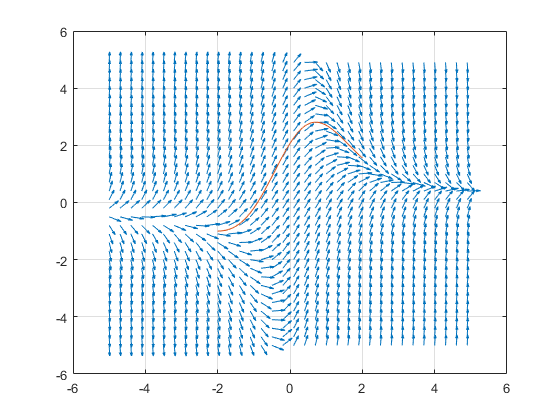

grid on

quiver(t,y,u./l,v./l)
t0 = [-2,2]

t0 =     -2     2


[t,y]= ode45(f,t0,-1)

t =   -2.000000000000000
  -1.900000000000000
  -1.800000000000000
  -1.700000000000000
  -1.600000000000000
  -1.500000000000000
  -1.400000000000000
  -1.300000000000000
  -1.200000000000000
  -1.100000000000000


y =   -1.000000000000000
  -0.994669095804680
  -0.977282747292452
  -0.945792160267827
  -0.898204086793861
  -0.832647974693451
  -0.747514599370689
  -0.641601042589036
  -0.514179957624896
  -0.365065612716626


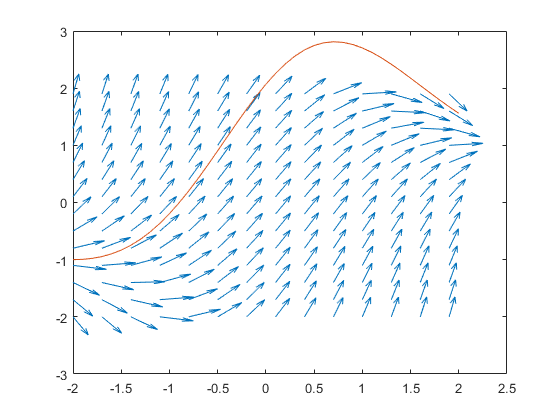

hold on
plot(t,y)
hold off

clear all
syms y(t)
hold on
edo1 = diff(y(t),t)==2 - t.*y

$$edo1(t) = \frac{\partial }{\partial t}y\left(t\right)=2-t\,y\left(t\right)$$

s3=dsolve(edo1,y(-2)==-1)

$$s3 = -{\mathrm{e}}^{-\frac{t^{2}}{2}}\,\left({\mathrm{e}}^{2}+\sqrt{2}\,\sqrt{\pi }\,\mathrm{erf}\left(\sqrt{2}\,\mathrm{i}\right)\,\mathrm{i}\right)-\sqrt{2}\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{t^{2}}{2}}\,\mathrm{erf}\left(\frac{\sqrt{2}\,t\,\mathrm{i}}{2}\right)\,\mathrm{i}$$

c3=fplot(s3,[-2,2])

c3 =   FunctionLine with properties:

     Function: [1×1 sym]
       XRange: [-2 2]
        Color: [0.9290 0.6940 0.1250]
    LineStyle: '-'
    LineWidth: 0.5000

  Show all properties


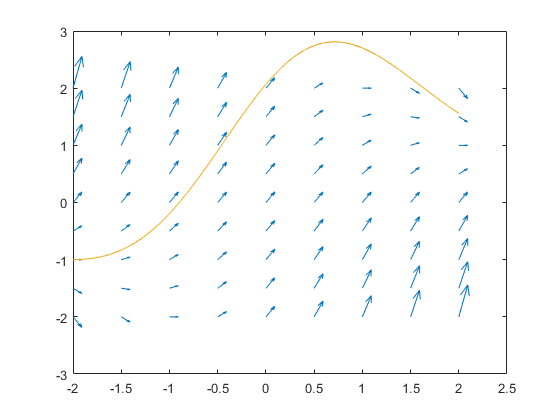

hold off

clear all
syms y(t)
edo1 = diff(y(t),t)==y(t)

$$edo1 = \frac{\partial }{\partial t}y\left(t\right)=y\left(t\right)$$

dsolve(edo1)

$$ans = C_{1}\,{\mathrm{e}}^{t}$$

clear all
syms y(t)
dsolve(diff(y(t),t)==y(t))

$$ans = C_{1}\,{\mathrm{e}}^{t}$$

S2 = dsolve(diff(y(t),t)==y(t), y(0)==1)

$$S2 = {\mathrm{e}}^{t}$$

C1 = fplot(S2,[-2,1])

C1 =   FunctionLine with properties:

     Function: [1×1 sym]
       XRange: [-2 1]
        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 0.5000

  Show all properties


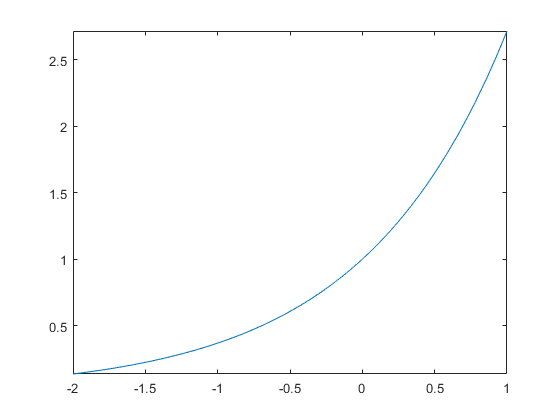

hold off